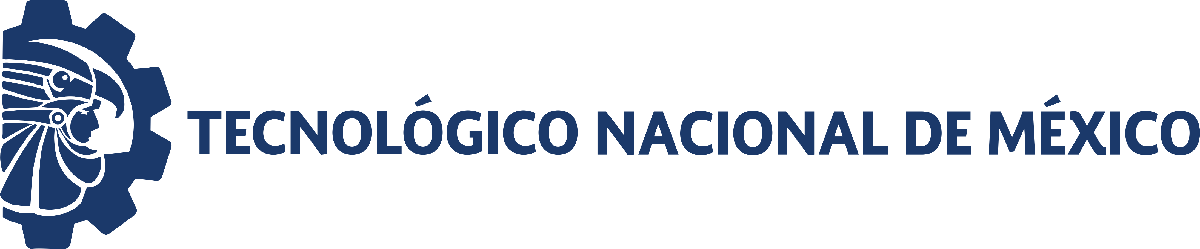                                 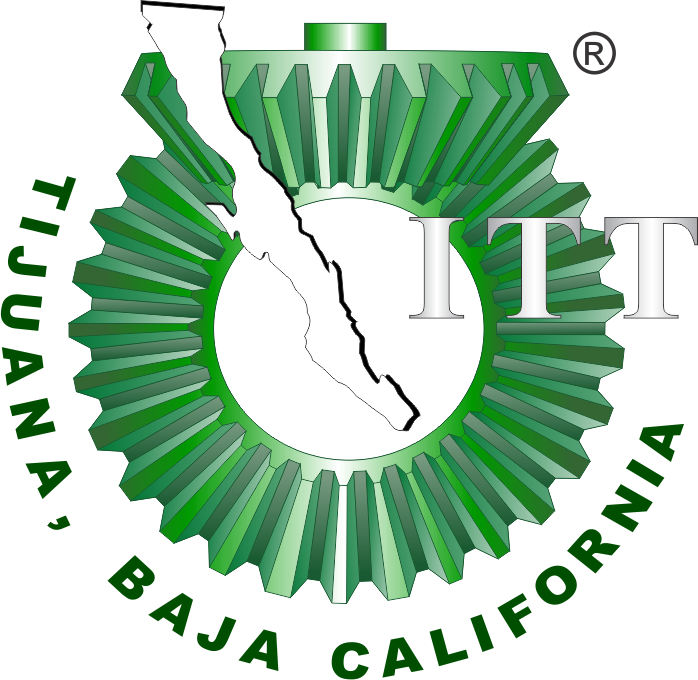

# Práctica 2: Sistema respiratorio

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

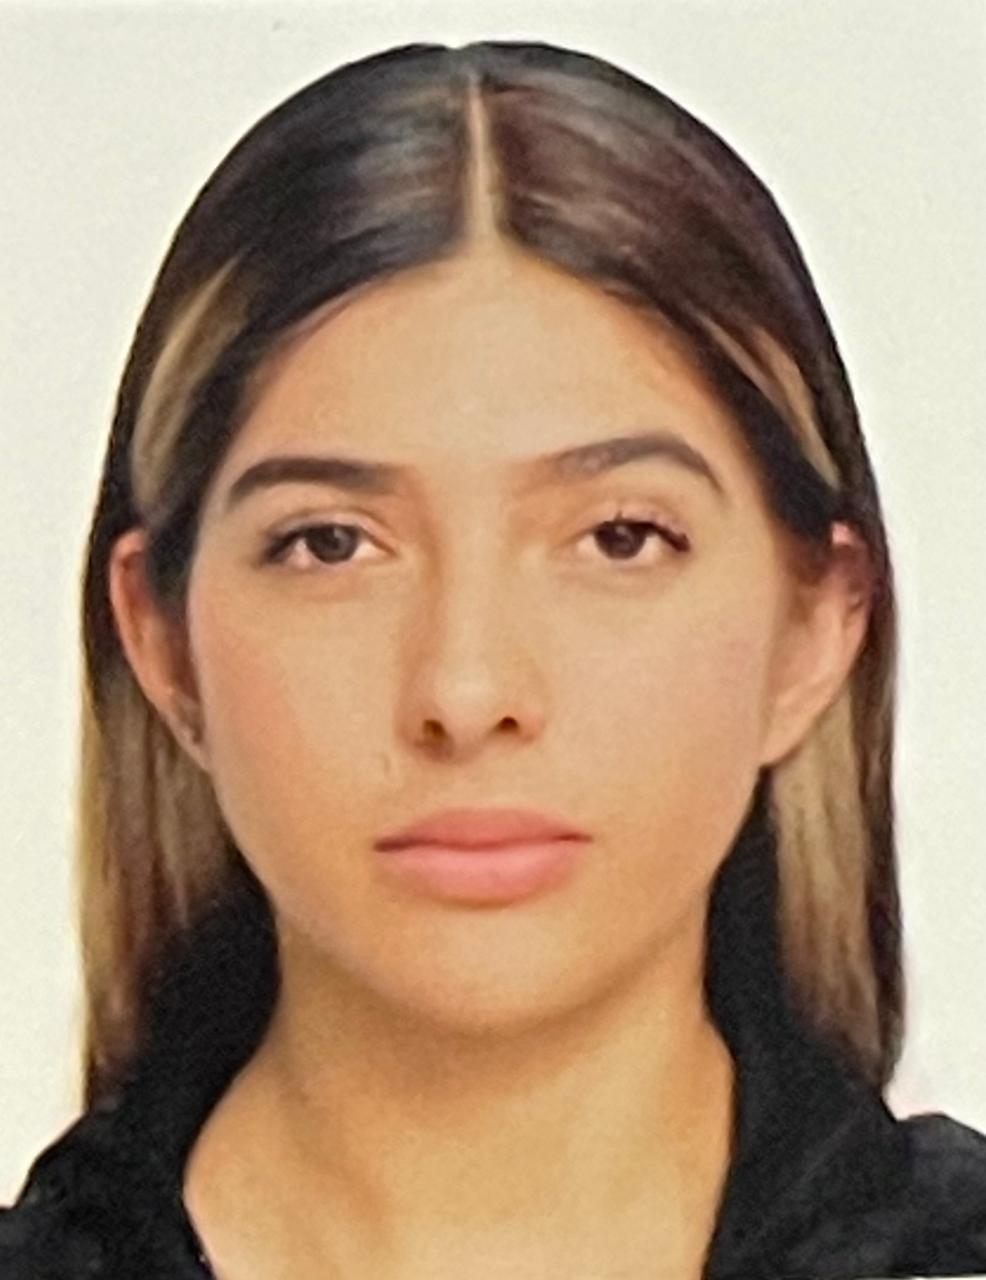

Nombre del alumno: **Gonzalez Garcia Josselin**

Número de control: **C21210380**

Correo institucional: **l21210380@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend='30';
file = 'GonzalezGC21210380P2';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode15';
parameters.MaxStep= '1E-3';
parameters.StopTime= '30';
Controlador = 'PID';

## Rendimiento del controlador

kP=15.8953606940144

kI=452.120770004536

kD=0.0428965162903509

Settling time=0.0994 seg

Overshoot=9.37%

Peak=1.09

## Respiracion elevada

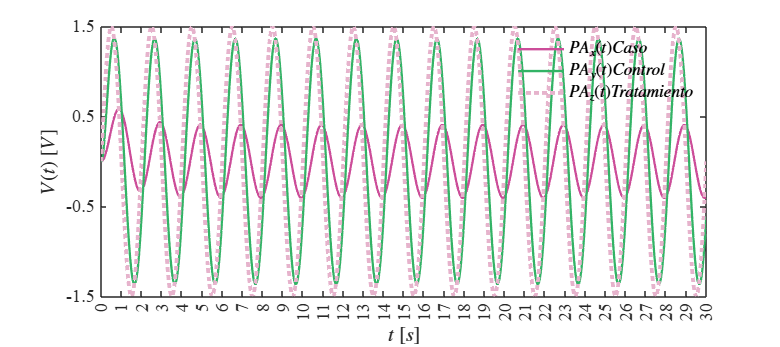

Signal = 'Respiracion elevada';
set_param('GonzalezGC21210380P2/PID Controller','P','15.8954');
set_param('GonzalezGC21210380P2/PID Controller','I','452.1208');
set_param('GonzalezGC21210380P2/PID Controller','D','0.042897');
set_param('GonzalezGC21210380P2/Pao(t)','sw','1');
set_param('GonzalezGC21210380P2/Pao(t)', 'sw', '0');
N = sim(file,parameters);
plotsignals(N.t,N.PAx,N.PAy,N.PAz,N.Pao,Signal)

## Respiracion normal

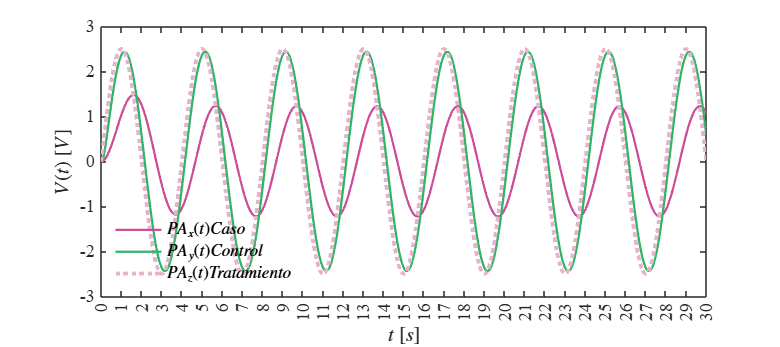

Signal = 'Respiracion normal';
set_param('GonzalezGC21210380P2/PID Controller','P','15.8954');
set_param('GonzalezGC21210380P2/PID Controller','I','452.1208');
set_param('GonzalezGC21210380P2/PID Controller','D','0.042897');
set_param('GonzalezGC21210380P2/Pao(t)','sw','0');
set_param('GonzalezGC21210380P2/Pao(t)', 'sw', '1');
N = sim(file,parameters);
plotsignals(N.t,N.PAx,N.PAy,N.PAz,N.Pao,Signal)

## Funcion: Respuesta a las señales

function plotsignals(t, Pao,PAx,PAy,PAz,Signal)
set (figure(),'Color','w')
set(gcf,'Units','Centimeters','Position',[1,3,18,8])
set(gca,'FontName','Times New Roman')
fontsize(12,'points')

Azul = [0.1,0.3,0.9];
Rosa = [0.8,0.3,0.6];
Naranja = [0.9,0.7,0.8];
Verde  = [0.2, 0.7, 0.4];

hold on; grid off; box on

plot (t,PAx,'LineWidth',1.5,'Color', Rosa)
plot (t,PAy,'LineWidth',1.5,'Color', Verde)
plot (t,PAz,':','LineWidth', 2.5, 'Color', Naranja)

xlabel('$t$ $[s]$', 'Interpreter', 'Latex')
ylabel('$V(t)$ $[V]$', 'Interpreter', 'Latex')

L = legend( '$PA_x(t)Caso$', '$PA_y(t)Control$', '$PA_z(t)Tratamiento$');
set(L, 'Interpreter','Latex','Location', 'Best', 'Box', 'Off')

if Signal == "Respiracion normal"
    xlim([0,30]); xticks(0:1:30)
    ylim([-3, 3]); yticks(-3:1:3)
    

elseif Signal == "Respiracion elevada"
    xlim([0,30]); xticks(0:1:30)
    ylim([-1.5, 1.5]); yticks(-1.5:1:1.5)
   

end 
exportgraphics(gcf,[Signal,'.pdf'], 'ContentType','Vector')

end
